# Driven Damped Pendulum

$m L^{2} \ddot{\phi}=-b L^{2} \dot{\phi}-m g L \sin \phi+L F(t)$       ***where  ***    $F(t)=F_{\mathrm{o}} \cos (\omega t)$


$$\ddot{\phi}+\frac{b}{m} \dot{\phi}+\frac{g}{L} \sin \phi=\frac{F_{\mathrm{o}}}{m L} \cos \omega t$$
       
$$\to$$
      
$$\frac{b}{m}=2 \beta$$
        
$$\frac{g}{L}=\omega_{o}^{2}$$
       
$$\gamma=\frac{F_{\mathrm{o}}}{m L \omega_{\mathrm{o}}^{2}}=\frac{F_{\mathrm{o}}}{m g}$$



$$\ddot{\phi}+2 \beta \dot{\phi}+\omega_{0}^{2} \sin \phi=\gamma \omega_{0}^{2} \cos \omega t$$


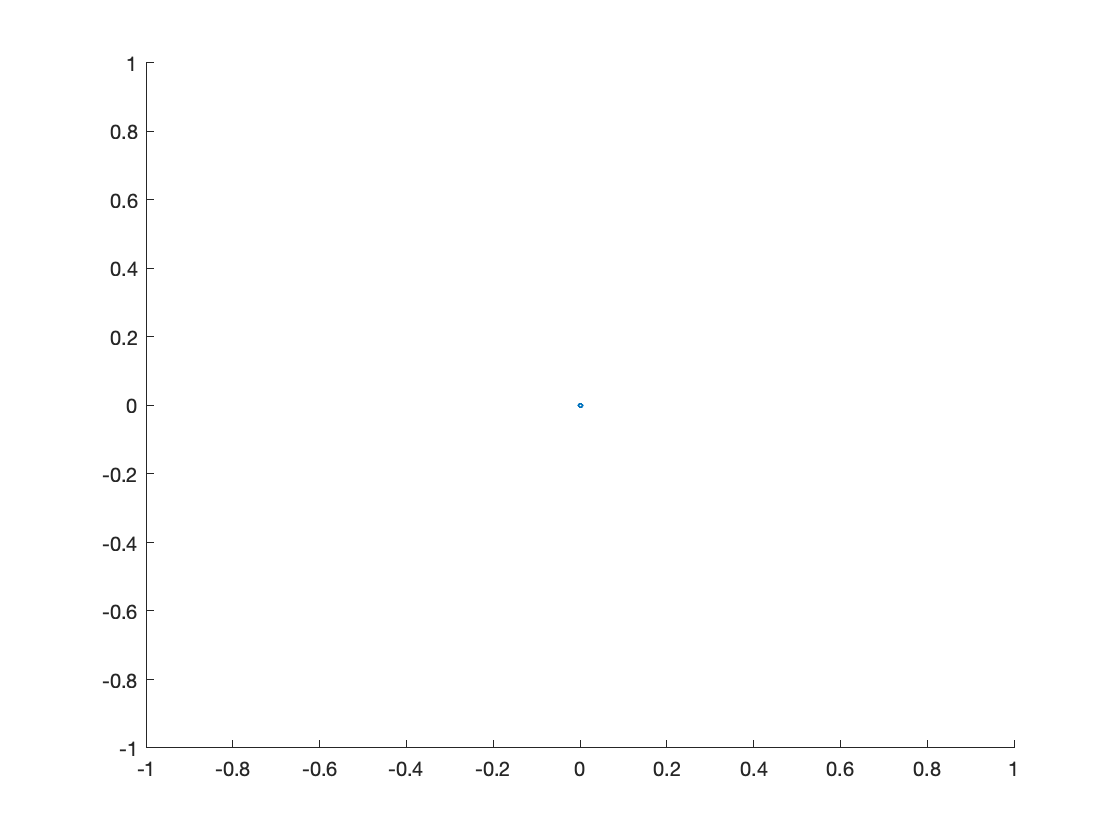

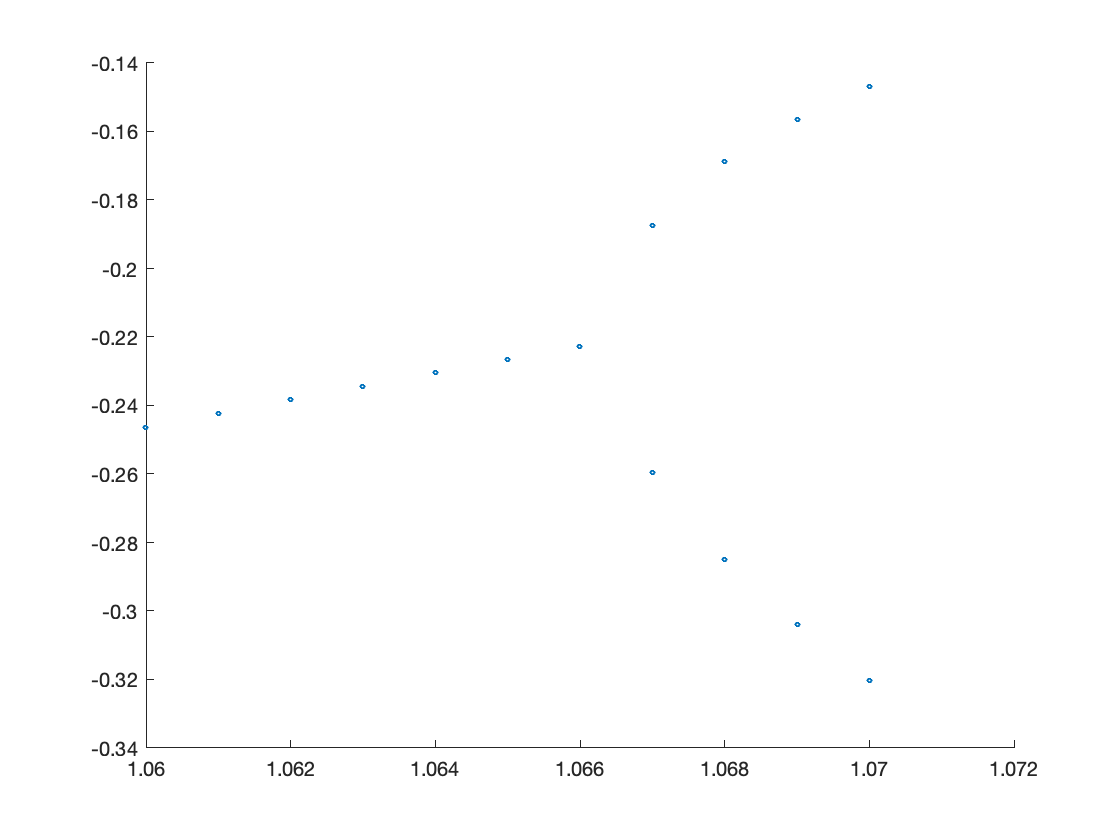

clear all
% equation parameters
params = struct('omega',(2*pi));
params.gamma = 1.5;
params.omega_0 = 1.5*params.omega;
params.beta = params.omega_0/4;
% Initial conditions
conds = struct('tstart',0,'bifurcationstart',500,'tend',600,...
    'y_0',-pi/2,'dy_0',0,'linewidth',0.3,'pointsize',0.3,...
    'reltol',1e-7,'abstol',1e-7,'stats','off');
conds.numpoints = conds.tend - conds.bifurcationstart;
% range of gamma values to sample
conds.gstart = 1.060;
conds.gend = 1.087;
conds.samplefreq = 1000; 

equ1 = odegetddpequation(params);
sol = odenumericsolve(equ1, conds);

% odemotionplot(sol, conds);
% odestatespaceplot2d(sol, conds);
% odestatespacewrappedplot2d(sol, conds);
% odepoincareplot(sol, conds);
D = odebifurcationdata(params, conds)
% x = D.x;
% y = D.y;
% scatter(x(:), y(:), 0.3)


% clear all
% S = load('BifurcationDiagram.mat');
% x = S.data.x;
% y = S.data.y;
% scatter(x(:), y(:), 0.3)